Détection réussie: 3 cycles identifiés.


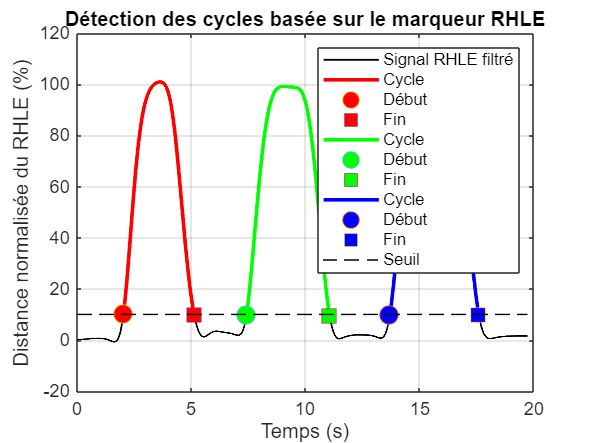

%% ================= Traitement cinématique ================= %%       
clear; clc; close all;

%% -------- Chargement de l'environnement -------- %%
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\3D Kinematics and Inverse Dynamics'));

%% -------- Sélection du mouvement  -------- %%
choice = 3; % Modifier pour changer de mouvement

Subjects = {'YL03'}; 
subj_idx = 1; % Vérifie que subj_idx est bien défini
% 'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
% 'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
% 'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
% 'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
% 'TM24', 'EG25', 'RL26'

% Définition du fichier
file_names = {... 
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL1-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL2-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL3-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL4-.c3d', Subjects{subj_idx}, Subjects{subj_idx}) ...
};

chemin_dossier = sprintf('C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s', Subjects{subj_idx});
fichier = fullfile(chemin_dossier, file_names{choice});

% Lecture du fichier C3D
c3dH = btkReadAcquisition(fichier);

%% -------- Extraction des marqueurs -------- %%
markers = btkGetMarkers(c3dH);
nFrames = btkGetLastFrame(c3dH);
fs = 200;
time = (0:nFrames-1) / fs;
time_norm = linspace(0, 1, length(time));

%% -------- Détection des cycles de mouvement basés sur le marqueur RHLE -------- %%
% Extraction des positions du marqueur RHLE
if isfield(markers, 'RHLE')
    % Calculer la position de référence (moyenne des 100 premières frames)
    RHLE_baseline = mean(markers.RHLE(1:min(100, nFrames), :));
    
    % Calculer la distance euclidienne entre position actuelle et position de référence
    RHLE_distance = sqrt(sum((markers.RHLE - repmat(RHLE_baseline, size(markers.RHLE, 1), 1)).^2, 2));
    
    % Normaliser la distance par rapport à la distance maximale (0-100%)
    RHLE_distance_max = max(RHLE_distance);
    RHLE_distance_normalized = (RHLE_distance / RHLE_distance_max) * 100;
    
    % Filtrage pour lisser la courbe de distance
    fc = 1; % Fréquence de coupure pour le filtre
    [b, a] = butter(2, fc / (fs/2), 'low');
    RHLE_distance_filtered = filtfilt(b, a, RHLE_distance_normalized);
    
    % Détection des cycles basée sur le franchissement d'un seuil
    threshold_pct = 10; % Seuil de la distance maximale (ajustable)
    min_cycle_duration = 0.5 * fs; % Durée minimale d'un cycle (0.5 seconde)
    
    % Initialisation des variables pour détecter les cycles
    cycle_starts = [];
    cycle_ends = [];
    in_cycle = false;
    last_start = 0;
    
    for i = 2:length(RHLE_distance_filtered)
        % Détection du début d'un cycle (franchissement du seuil à la montée)
        if ~in_cycle && RHLE_distance_filtered(i) > threshold_pct && RHLE_distance_filtered(i-1) <= threshold_pct
            in_cycle = true;
            last_start = i;
        % Détection de la fin d'un cycle (retour sous le seuil après une durée minimale)
        elseif in_cycle && RHLE_distance_filtered(i) < threshold_pct && RHLE_distance_filtered(i-1) >= threshold_pct && (i - last_start) > min_cycle_duration
            in_cycle = false;
            cycle_starts = [cycle_starts, last_start];
            cycle_ends = [cycle_ends, i];
        end
    end
    
    % Vérification du nombre de cycles détectés
    num_cycles = min(length(cycle_starts), length(cycle_ends));
    
    if num_cycles >= 3
        % Conserver seulement les 3 premiers cycles
        cycle_starts = cycle_starts(1:3);
        cycle_ends = cycle_ends(1:3);
        fprintf('Détection réussie: 3 cycles identifiés.\n');
    elseif num_cycles > 0
        fprintf('Attention: Seulement %d cycles détectés au lieu de 3.\n', num_cycles);
    else
        fprintf('Erreur: Aucun cycle détecté. Ajustez le seuil ou vérifiez les données.\n');
    end
    
    % Stocker les indices de frames pour chaque cycle
    cycles_frames = cell(num_cycles, 1);
    for i = 1:num_cycles
        cycles_frames{i} = cycle_starts(i):cycle_ends(i);
    end
    
    % Visualisation des cycles détectés
    figure;
    plot(time, RHLE_distance_filtered, 'k-', 'LineWidth', 1);
    hold on;
    
    colors = {'r', 'g', 'b'};
    for i = 1:num_cycles
        plot(time(cycles_frames{i}), RHLE_distance_filtered(cycles_frames{i}), colors{i}, 'LineWidth', 2);
        plot(time(cycle_starts(i)), RHLE_distance_filtered(cycle_starts(i)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', colors{i});
        plot(time(cycle_ends(i)), RHLE_distance_filtered(cycle_ends(i)), 's', 'MarkerSize', 10, 'MarkerFaceColor', colors{i});
    end
    
    % Affichage du seuil utilisé
    plot([time(1), time(end)], [threshold_pct, threshold_pct], 'k--');
    
    title('Détection des cycles basée sur le marqueur RHLE');
    xlabel('Temps (s)');
    ylabel('Distance normalisée du RHLE (%)');
    legend(['Signal RHLE filtré', repmat({'Cycle', 'Début', 'Fin'}, 1, num_cycles), 'Seuil']);
    grid on;
else
    warning('Le marqueur RHLE n''est pas disponible dans les données.');
    cycles_frames = {1:nFrames}; % Utiliser toutes les frames si RHLE n'est pas disponible
    num_cycles = 1;
end

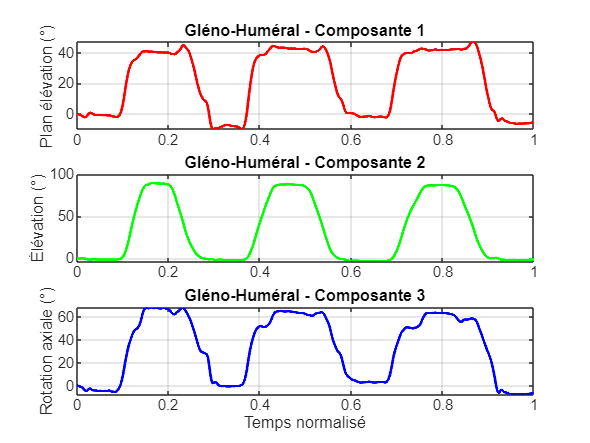


% Sauvegarde de l'information des cycles pour utilisation ultérieure
% (après le calcul des angles)
save_cycles_info = true; % False si non-sauvegarde
if save_cycles_info
    save('cycles_info.mat', 'cycles_frames', 'num_cycles', 'time');
end

%% -------- Initialisation des matrices pour stocker les angles -------- %%
Angles_GH = zeros(nFrames, 3);
Angles_ST = zeros(nFrames, 3);
Angles_HT = zeros(nFrames, 3);
normalize_vector = @(v) v / norm(v);

%% ======== Extraction des angles d'Euler selon Wu et al. 2005 ======== %%
for i = 1:nFrames

    % Etape 1 : Définition des repères segmentaires %

    % Repère du thorax
    SJN = markers.SJN(i,:); CV7 = markers.CV7(i,:);
    TV8 = markers.TV8(i,:); SXS = markers.SXS(i,:);
    Ot = SJN;
    Yt = normalize_vector(mean([SXS; TV8]) - mean([SJN; CV7]));
    Zt = normalize_vector(cross(SJN - CV7, mean([SXS; TV8]) - SJN));
    Xt = normalize_vector(cross(Yt, Zt));
    
    % Repère de la scapula
    RSAA = markers.RSAA(i,:); RSRS = markers.RSRS(i,:); RSIA = markers.RSIA(i,:);
    Os = RSAA;
    Zs = normalize_vector(RSAA - RSRS);
    Xs = normalize_vector(cross(RSIA - RSAA, RSRS - RSAA));
    Ys = normalize_vector(cross(Xs, Zs));
    
    % Repère de l'humérus
    RGH = markers.RSCT(i,:); RHME = markers.RHME(i,:); RHLE = markers.RHLE(i,:);
    Rmid_HLE_HME = mean([RHLE; RHME]);
    Oh = RGH;
    Yh = normalize_vector(RGH - Rmid_HLE_HME);
    Xh = normalize_vector(cross(RGH - RHLE, RGH - RHME));
    Zh = normalize_vector(cross(Yh, Xh));

    % Etape 2 : Calcul des matrices de rotation %

    % Matrices de rotation par rapport au repère global
    Rt = [Xt', Yt', Zt'];
    Rs = [Xs', Ys', Zs'];
    Rh = [Xh', Yh', Zh'];
    
    % Correction orthonormalité (A^T=A = I)
    % Utilisation de "svd" pour garantir que les matrices R sont orthogonales
    [Ut,~,Vt] = svd(Rt); Rt = Ut * Vt';
    [Us,~,Vs] = svd(Rs); Rs = Us * Vs';
    [Uh,~,Vh] = svd(Rh); Rh = Uh * Vh';

    % Matrices de rotation relatives
    R_HT = Rt' * Rh;  % Humérus par rapport au thorax
    R_ST = Rt' * Rs;  % Scapula par rapport au thorax
    R_GH = Rs' * Rh;  % Humérus par rapport à la scapula

    % Etape 3 : Extraction des angles d'Euler selon une séquence spécifique pour chaque angle 

    Angles_HT(i,:) = squeeze(R2mobileYXY_array3(reshape(R_HT,3,3,1))); % Huméro-Thoracique
    Angles_ST(i,:) = squeeze(R2mobileYXZ_array3(reshape(R_ST,3,3,1))); % Scapulo-Thoracique
    Angles_GH(i,:) = squeeze(R2mobileYXY_array3(reshape(R_GH,3,3,1))); % Gléno-Huméral
end

%% -------- Filtrage et correction des discontinuités -------- %%

% Utilisation de la fonction "unwrap" pour limiter les sauts de cardan liés aux angles de Euler 
Angles_GH = unwrap(Angles_GH);
Angles_ST = unwrap(Angles_ST);
Angles_HT = unwrap(Angles_HT);

% Filtrage passe-bas pour limiter les variations des données des marqueurs et de potentiels données 
fc = 6;
[b, a] = butter(2, fc / (fs/2), 'low');
Angles_GH = filtfilt(b, a, Angles_GH);
Angles_ST = filtfilt(b, a, Angles_ST);
Angles_HT = filtfilt(b, a, Angles_HT);

% Recentrage des angles pour éliminer un biais initial (ex : commencer à -200°) et recentrer les courbes
Angles_GH(:,3) = Angles_GH(:,3) - mean(Angles_GH(1:10,3));
Angles_ST(:,3) = Angles_ST(:,3) - mean(Angles_ST(1:10,3));
Angles_HT(:,3) = Angles_HT(:,3) - mean(Angles_HT(1:10,3));

Angles_GH(:,2) = Angles_GH(:,2) - mean(Angles_GH(1:10,2));
Angles_ST(:,2) = Angles_ST(:,2) - mean(Angles_ST(1:10,2));
Angles_HT(:,2) = Angles_HT(:,2) - mean(Angles_HT(1:10,2));

Angles_GH(:,1) = Angles_GH(:,1) - mean(Angles_GH(1:10,1));
Angles_ST(:,1) = Angles_ST(:,1) - mean(Angles_ST(1:10,1));
Angles_HT(:,1) = Angles_HT(:,1) - mean(Angles_HT(1:10,1));

%% -------- Affichage séparé des angles pour chaque articulation -------- %%

% Figure 1 : Angles GH
figure;
subplot(3,1,1);
plot(time_norm, rad2deg(Angles_GH(:,1)), 'r', 'LineWidth', 1.5);
ylabel('Plan élévation (°)');
title('Gléno-Huméral - Composante 1');
grid on;

subplot(3,1,2);
plot(time_norm, rad2deg(Angles_GH(:,2)), 'g', 'LineWidth', 1.5);
ylabel('Élévation (°)');
title('Gléno-Huméral - Composante 2');
grid on;

subplot(3,1,3);
plot(time_norm, rad2deg(Angles_GH(:,3)), 'b', 'LineWidth', 1.5);
ylabel('Rotation axiale (°)');
xlabel('Temps normalisé');
title('Gléno-Huméral - Composante 3');
grid on;

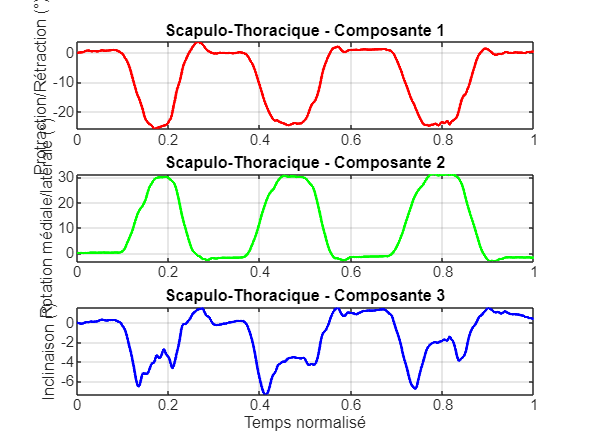


% Figure 2 : Angles ST
figure;
subplot(3,1,1);
plot(time_norm, rad2deg(Angles_ST(:,1)), 'r', 'LineWidth', 1.5);
ylabel('Protraction/Rétraction (°)');
title('Scapulo-Thoracique - Composante 1');
grid on;

subplot(3,1,2);
plot(time_norm, rad2deg(Angles_ST(:,2)), 'g', 'LineWidth', 1.5);
ylabel('Rotation médiale/latérale (°)');
title('Scapulo-Thoracique - Composante 2');
grid on;

subplot(3,1,3);
plot(time_norm, rad2deg(Angles_ST(:,3)), 'b', 'LineWidth', 1.5);
ylabel('Inclinaison (°)');
xlabel('Temps normalisé');
title('Scapulo-Thoracique - Composante 3');
grid on;

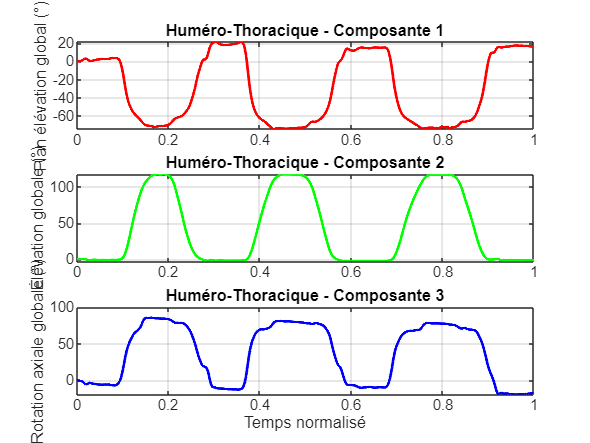


% Figure 3 : Angles HT
figure;
subplot(3,1,1);
plot(time_norm, rad2deg(Angles_HT(:,1)), 'r', 'LineWidth', 1.5);
ylabel('Plan élévation global (°)');
title('Huméro-Thoracique - Composante 1');
grid on;

subplot(3,1,2);
plot(time_norm, rad2deg(Angles_HT(:,2)), 'g', 'LineWidth', 1.5);
ylabel('Élévation globale (°)');
title('Huméro-Thoracique - Composante 2');
grid on;

subplot(3,1,3);
plot(time_norm, rad2deg(Angles_HT(:,3)), 'b', 'LineWidth', 1.5);
ylabel('Rotation axiale globale (°)');
xlabel('Temps normalisé');
title('Huméro-Thoracique - Composante 3');
grid on;

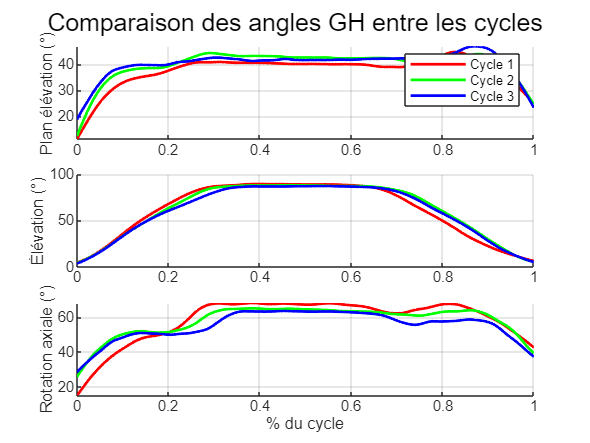

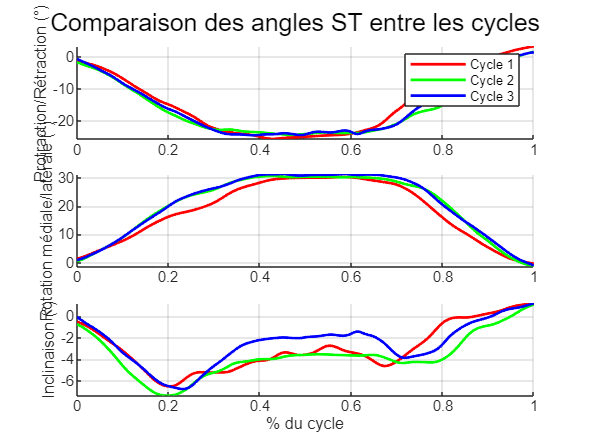

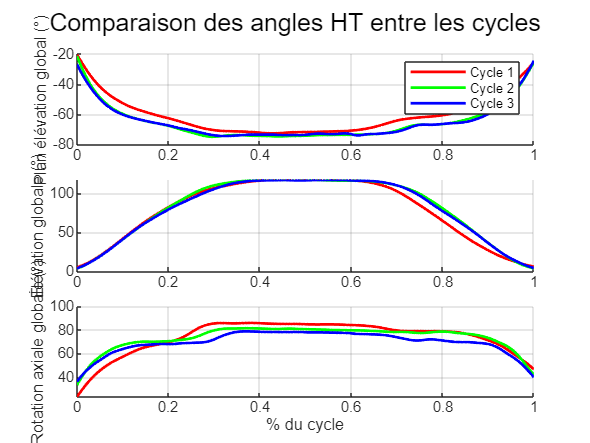


%% -------- Visualisation des angles par cycle -------- %%
% Charger les informations des cycles si nécessaire
if ~exist('cycles_frames', 'var')
    if exist('cycles_info.mat', 'file')
        load('cycles_info.mat');
    else
        warning('Information des cycles non disponible. Utilisation de toutes les données.');
        cycles_frames = {1:nFrames};
        num_cycles = 1;
    end
end

% Création d'une figure pour comparer les angles entre les cycles
if num_cycles > 0
    angle_types = {'GH', 'ST', 'HT'};
    angle_components = {
        {'Plan élévation (°)', 'Élévation (°)', 'Rotation axiale (°)'}, 
        {'Protraction/Rétraction (°)', 'Rotation médiale/latérale (°)', 'Inclinaison (°)'}, 
        {'Plan élévation global (°)', 'Élévation globale (°)', 'Rotation axiale globale (°)'}
    };
    
    colors = {'r', 'g', 'b'};
    
    for a = 1:length(angle_types)
        figure;
        sgtitle(['Comparaison des angles ' angle_types{a} ' entre les cycles']);
        
        for c = 1:3 % Composantes (X, Y, Z)
            subplot(3, 1, c);
            hold on;
            
            for i = 1:num_cycles
                % Normaliser le temps pour chaque cycle (0-100%)
                cycle_time_norm = linspace(0, 1, length(cycles_frames{i}));
                
                % Récupérer les angles pour ce cycle
                switch angle_types{a}
                    case 'GH'
                        cycle_angles = Angles_GH(cycles_frames{i}, c);
                    case 'ST'
                        cycle_angles = Angles_ST(cycles_frames{i}, c);
                    case 'HT'
                        cycle_angles = Angles_HT(cycles_frames{i}, c);
                end
                
                % Tracer les angles pour ce cycle
                plot(cycle_time_norm, rad2deg(cycle_angles), colors{i}, 'LineWidth', 1.5);
            end
            
            ylabel(angle_components{a}{c});
            if c == 3
                xlabel('% du cycle');
            end
            grid on;
            
            if c == 1
                legend('Cycle 1', 'Cycle 2', 'Cycle 3');
            end
        end
    end
end